clear;clc;
% a) 视频处理
videoFile = 'run.mp4';
videoReader = VideoReader(videoFile); 
numFrames = videoReader.NumFrames;
video = read(videoReader);
Gray_video = zeros(size(video, 1), size(video, 2), size(video, 4));
for i = 1:numFrames
 temp = rgb2gray(video(:,:,:,i));
 Gray_video(:, :, i) = double(temp)/255;
end

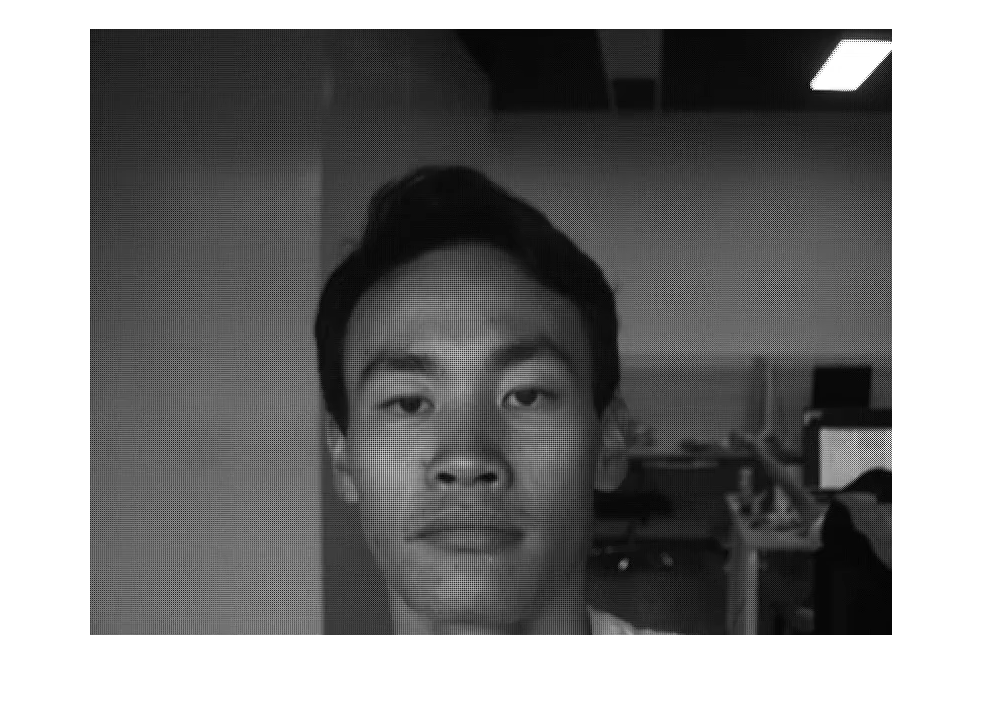

% b) 定义目标区域
Firstframe = Gray_video(:,:,1);
imshow(Firstframe);
rect = round(getrect); % 让用户选择目标区域，返回矢量[x y width height]

column = rect(1);
row = rect(2);
width = rect(3);
height = rect(4);
rectangle('Position',[column,row,width,height],'EdgeColor','r','LineWidth', 1.0);
hold off;                                                                                                                                                                                                 
target = zeros(numFrames, 4);
target(1,:) = [column,row,width,height];
sigma = sqrt(width*height)/10; 
gaussianResponse = fspecial('gaussian', [height, width], sigma);

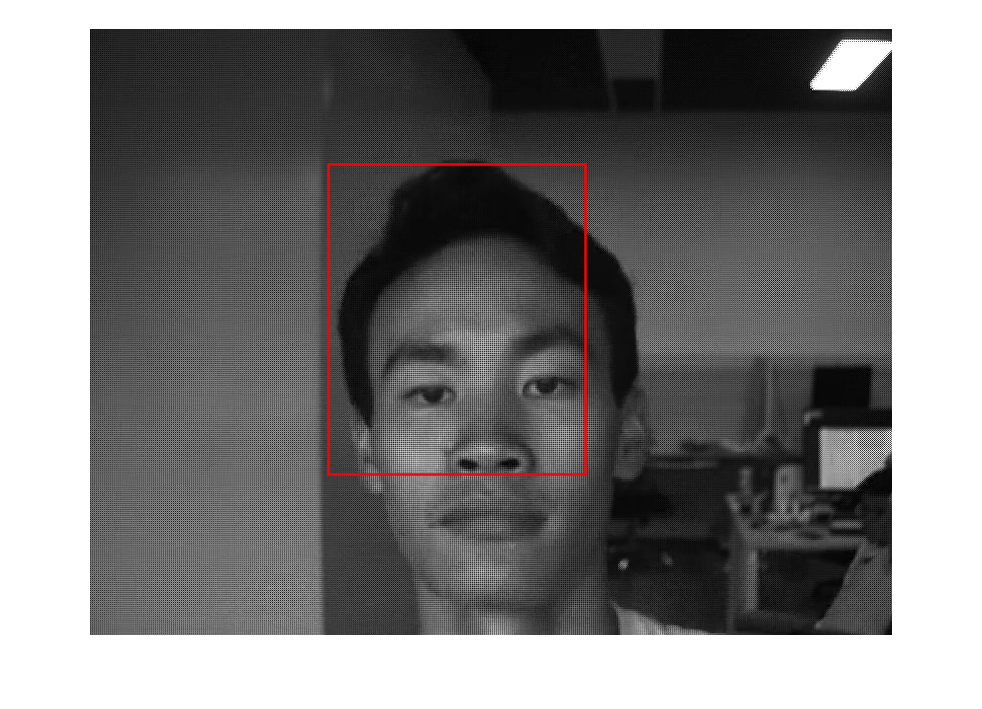

lambda = 1;
Malpha = 0.95;
W0 = zeros(height, width, numFrames);
W0(:,:,1) = MOSSE(Firstframe, gaussianResponse, target(1,:), lambda);
for i = 2 : numFrames
 imshow(Gray_video(:, :, i));
 hold on
 [W_new, frame_cropped] = MOSSE(Gray_video(:, :, i), gaussianResponse, target(i-1, :), lambda);
 W0(:, :, i) = Malpha*W0(:, :, i-1) + (1-Malpha)*W_new;
 Response = xcorr2(frame_cropped, W0(:,:,i-1));
 k = find(Response==max(Response, [], 'all'));
 [new_x, new_y] = ind2sub(size(Response), k); % 坐标转换
 dx = new_x - height;
 dy = new_y - width;
 target(i, :) = [target(i - 1, 1) + dy, target(i - 1, 2) + dx, width, height];
 rectangle('Position', target(i,:),'EdgeColor', 'r','LineWidth', 1.5);
 hold off;
 pause(0.1);
end                                                                                     

v = VideoWriter("run_tar.mp4", 'MPEG-4');
open(v);
for idx = 1:numFrames
    frame = Gray_video(:, :, idx);
    frameRGB = repmat(frame, [1, 1, 3]);  % 将灰度帧转换为RGB帧
    frameRGB = insertShape(frameRGB, 'Rectangle', target(idx,:), 'Color', 'r', 'LineWidth', 2);
    writeVideo(v, frameRGB);
end
close(v);

function [W, frame_cropped] = MOSSE(img, Y, firstPoint, lambda)
[r2, c2] = size(Y);
X = img(firstPoint(2):firstPoint(2)+r2-1, firstPoint(1):firstPoint(1)+c2-1);
frame_cropped = X;
X = fft2(X);
Y = fft2(Y);
sxx = X .* conj(X);
sxy = X .* conj(Y);
W = sxy ./ (sxx + lambda);
W = real(ifftshift(ifft2(W)));
end 